## Rete Anticipatrice.

Tracciare, nello stesso grafico, i diagrammi di Bode della seguente funzione di trasferimento al variare del parametro 𝑚∈{1,2,3,5,10}.

- Il valore di 𝑚 è più indicato per avere un maggior incremento di fase in corrispondenza della pulsazione 10 [rad/𝑠] si ha per m=10 (vedi diagramma Bode).

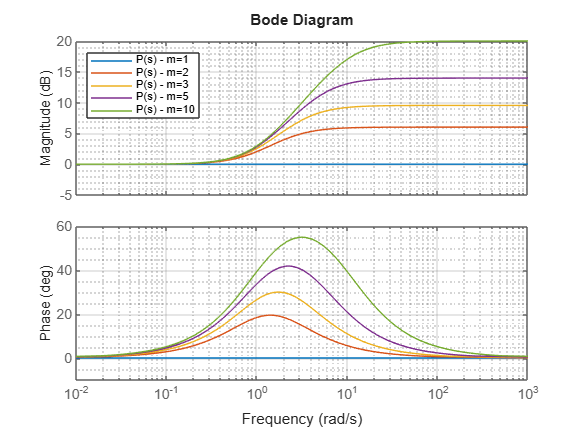

m = [1,2,3,5,10];
num = [0.1 1];

for index = 1:length(m)
    den = [0.01/m(index) 1]; % Si ricalcola il denominatore in base al valore di m.
    
    P_s = tf(num,den); % Si ricalcola la FdT in base al valore di m.
    
    bode(P_s)
    grid on
    grid minor
    hold on
end

hold off

legend("P(s) - m=1","P(s) - m=2","P(s) - m=3","P(s) - m=5","P(s) - m=10");
legend("Location","northwest");